clear
load_b_h_430f

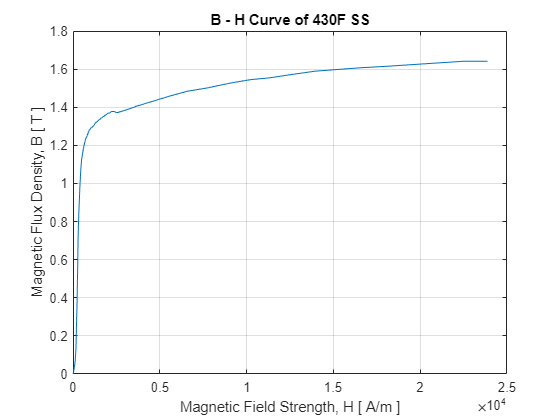

figure()
plot(bh430F.H_Oe*1E3/(4*pi),bh430F.B_Gauss/1E4)
title('B - H Curve of 430F SS'),grid on,xlabel('Magnetic Field Strength, H [ A/m ]'),ylabel('Magnetic Flux Density, B [ T ]')

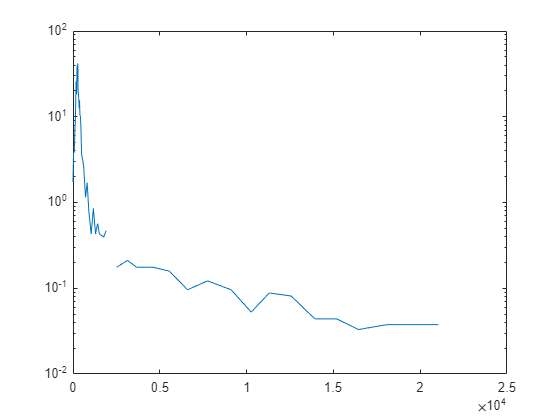

for i=2:length(bh430F.H_Oe)
    var_perm(i-1) = ((bh430F.B_Gauss(i)-bh430F.B_Gauss(i-1))/1E4)/(bh430F.H_Oe(i)-bh430F.H_Oe(i-1))*1E3/(4*pi);
end
figure()
semilogy(bh430F.H_Oe(1:end-1)*1E3/(4*pi),var_perm)

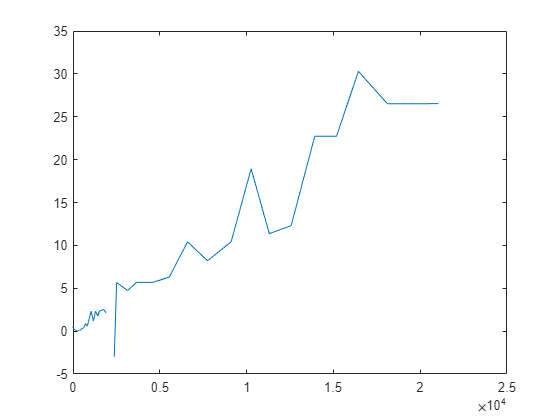

figure()
plot(bh430F.H_Oe(1:end-1)*1E3/(4*pi),1./var_perm)